Create summaryStruct (only run once)

% count = 1;
% 
% nPoints = 64;
% linspace_steps = 64;
% original_points = linspace(1.3, -1.3, linspace_steps);
% selected_idx = round(linspace(1, linspace_steps, nPoints));
% 
% exclusions = {'f', 'v', 'c', 'F', 'V', 'meshOutput', 'abaqusData', 'E_effectiveStrain', 'E_effectiveStress'};
% % exclusions = {'abaqusData'};
% 
% % Pre-allocate
% template = cell2struct(cell(size(expectedFields)), expectedFields, 1);
% summaryStruct = repmat(template, 1, linspace_steps);
% 
% for i = original_points(selected_idx)
% 
% defaultFolder = 'D:'; % Changed to external hard drive
% savePath=fullfile(defaultFolder,'TechnicalReport','LatticeProperties_LinearFinal',sprintf('%.5g_Lattice_Density',i));
% matlabPath=fullfile(savePath,'simulation_results.mat');
% 
% load(matlabPath);
% 
% % Define the expected fields (this might come from the first load)
% expectedFields = fieldnames(resultStruct);
% expectedFields = expectedFields(~ismember(expectedFields, exclusions));
% 
% % For each expected field, check if it exists in resultStruct; if not, assign empty
% for j = 1:numel(expectedFields)
%     fieldName = expectedFields{j};
%     if isfield(resultStruct, fieldName)
%         summaryStruct(count).(fieldName) = resultStruct.(fieldName);
%     else
%         summaryStruct(count).(fieldName) = [];  % Or assign a default value
%     end
% end
% 
% count = count + 1
% end
%
% savePath=fullfile(defaultFolder,'TechnicalReport','LatticeProperties_LinearFinal','!Summary');
% matlabPath=fullfile(savePath,'simulation_results_summary.mat');
% 
% save(matlabPath,'summaryStruct', '-v7.3')

defaultFolder = fullfile('D:','TechnicalReport','LatticeProperties_LinearFinal');
matPath = fullfile(defaultFolder,'!Summary','simulation_results_summary.mat');
load(matPath);

Plot Settings

blue   = [0, 0.4470, 0.7410];  % "#0072BD"
cyan  = [0.3010, 0.7450, 0.9330];  % "#4DBEEE"

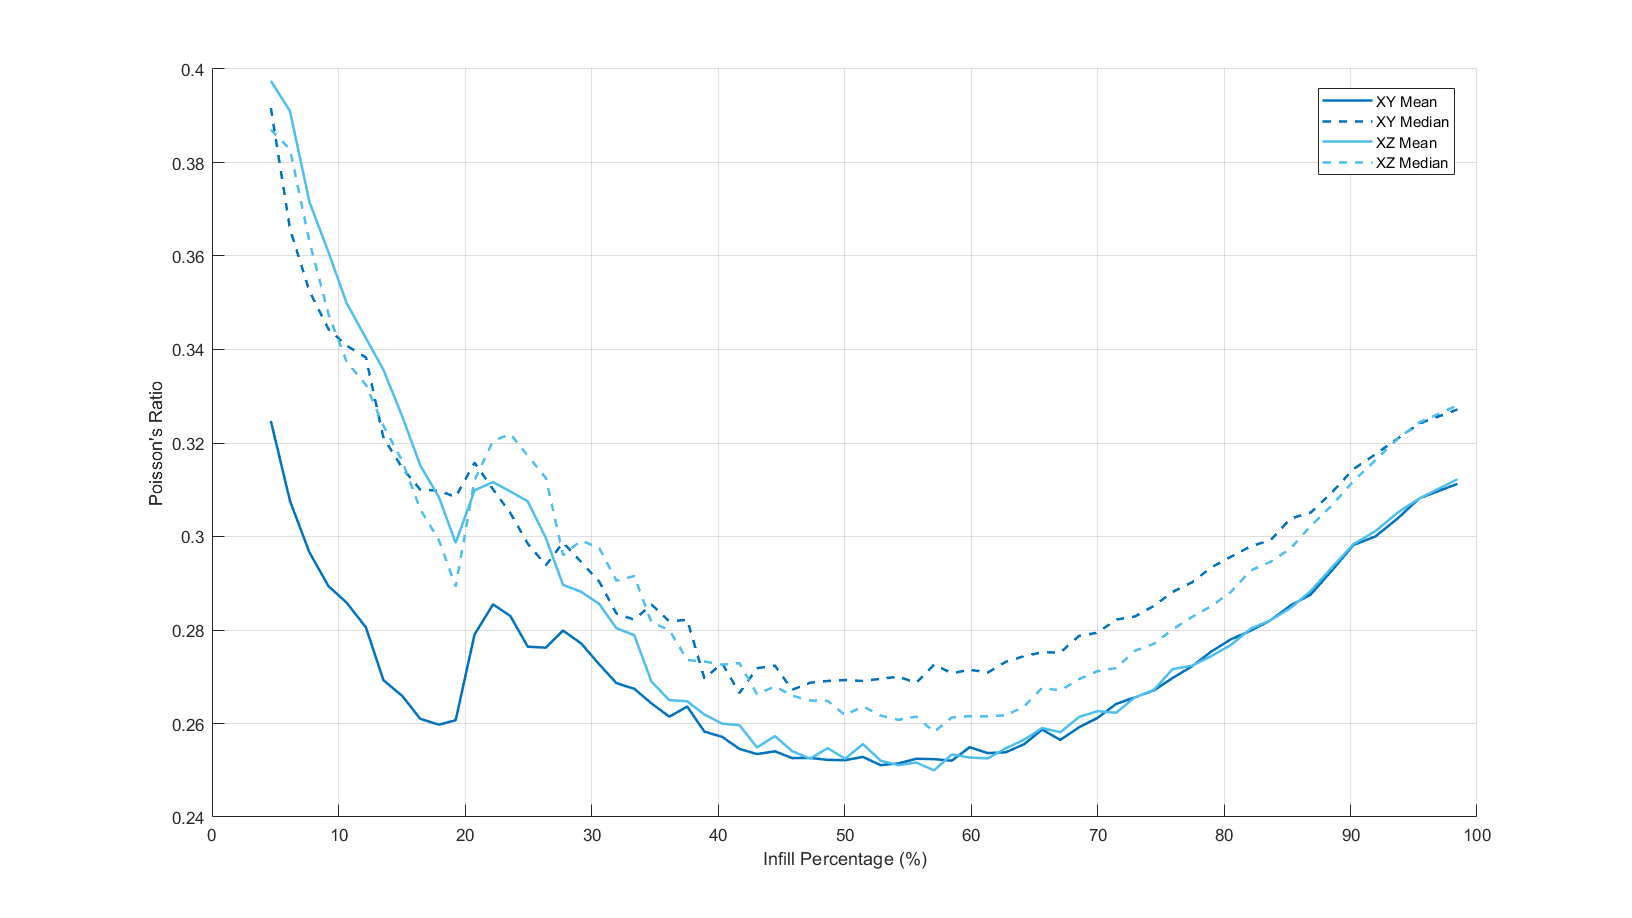

cFigure;
hold on; grid on;
plot(vertcat(summaryStruct.infill_percentage), vertcat(summaryStruct.poisson_xy_mean),'Color',blue, 'LineWidth', 1.5)
plot(vertcat(summaryStruct.infill_percentage), vertcat(summaryStruct.poisson_xy_median), '--','Color',blue, 'LineWidth', 1.5)
plot(vertcat(summaryStruct.infill_percentage), vertcat(summaryStruct.poisson_xz_mean),'Color',cyan, 'LineWidth', 1.5)
plot(vertcat(summaryStruct.infill_percentage), vertcat(summaryStruct.poisson_xz_median), '--','Color',cyan, 'LineWidth', 1.5)

legend('XY Mean', 'XY Median', 'XZ Mean', 'XZ Median', 'Location','best');
xlabel("Infill Percentage (%)")
ylabel("Poisson's Ratio")

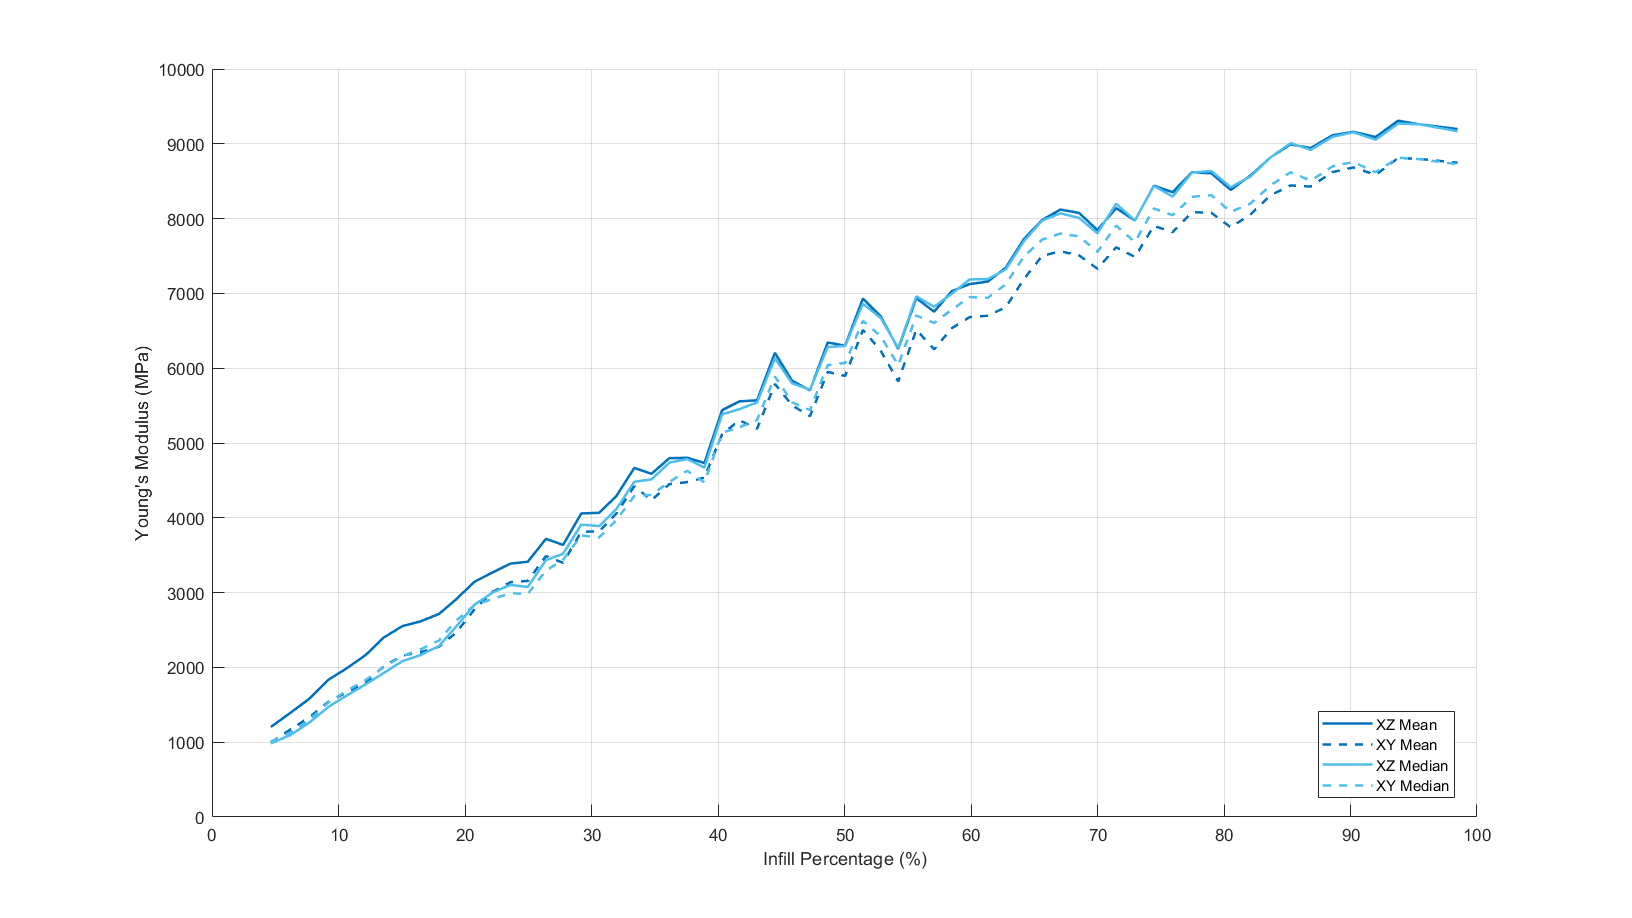

youngs_modulus = vertcat(summaryStruct.youngs_modulus);

cFigure;
hold on; grid on;
plot(vertcat(summaryStruct.infill_percentage), vertcat(youngs_modulus.youngs_modulus_xy_mean),'Color',blue, 'LineWidth', 1.5)
plot(vertcat(summaryStruct.infill_percentage), vertcat(youngs_modulus.youngs_modulus_xy_median), '--','Color',blue, 'LineWidth', 1.5)
plot(vertcat(summaryStruct.infill_percentage), vertcat(youngs_modulus.youngs_modulus_xz_mean),'Color',cyan, 'LineWidth', 1.5)
plot(vertcat(summaryStruct.infill_percentage), vertcat(youngs_modulus.youngs_modulus_xz_median), '--','Color',cyan, 'LineWidth', 1.5)

legend('XZ Mean', 'XY Mean', 'XZ Median', 'XY Median','Location','best');
xlabel("Infill Percentage (%)")
ylabel("Young's Modulus (MPa)")

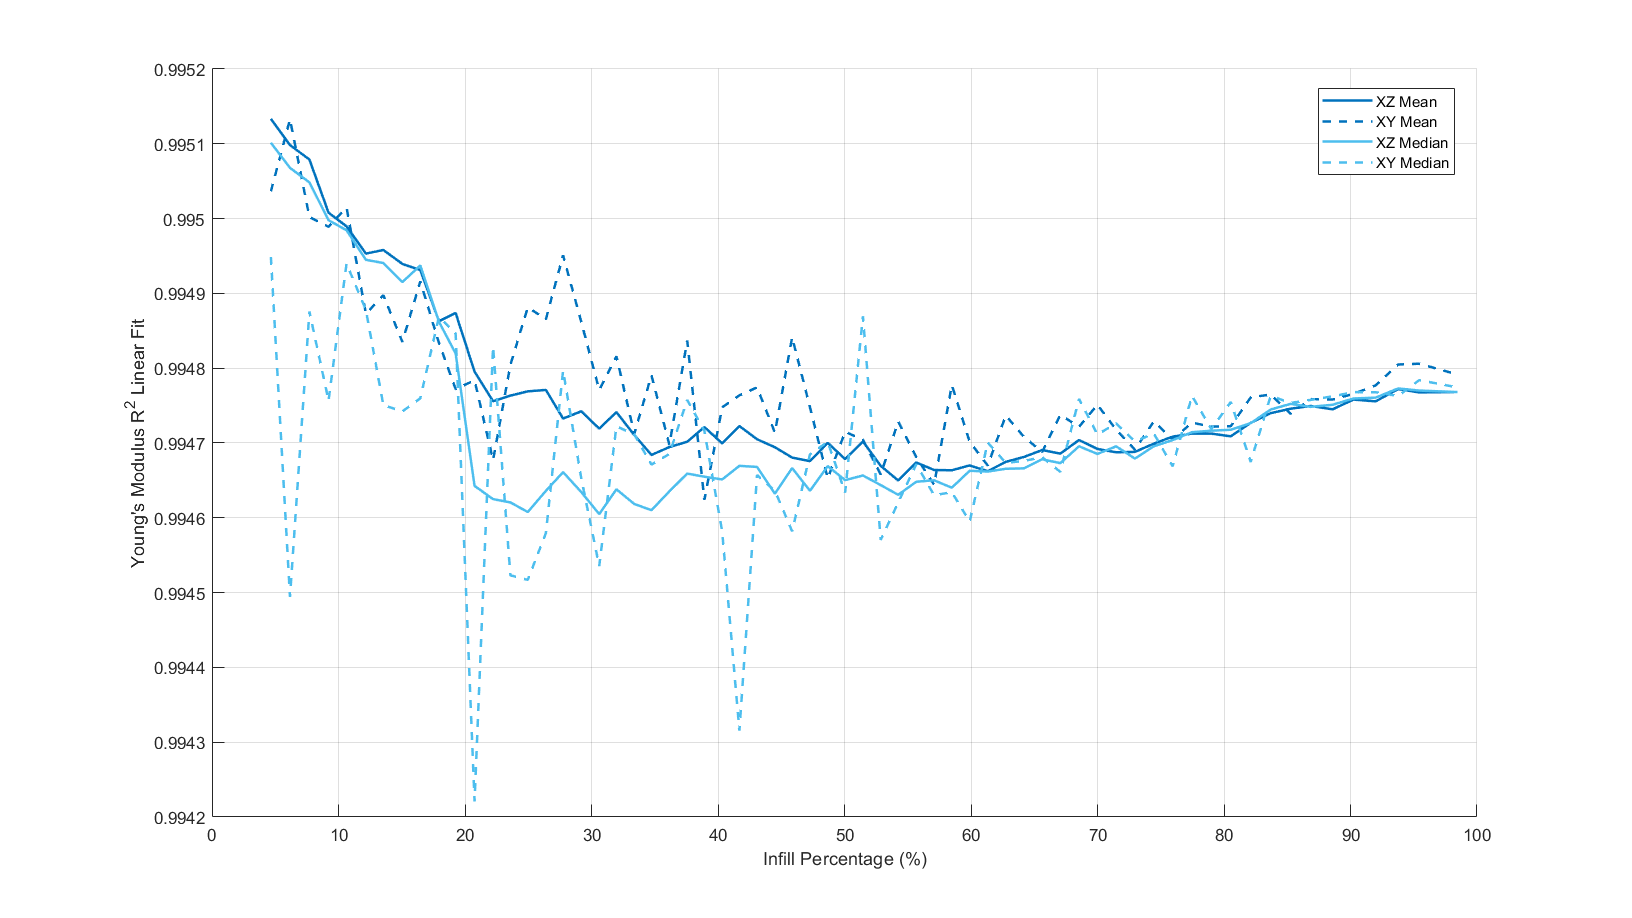

cFigure;
hold on; grid on;
plot(vertcat(summaryStruct.infill_percentage), vertcat(youngs_modulus.youngs_modulus_xy_mean_R_squared),'Color',blue, 'LineWidth', 1.5)
plot(vertcat(summaryStruct.infill_percentage), vertcat(youngs_modulus.youngs_modulus_xy_median_R_squared), '--','Color',blue, 'LineWidth', 1.5)
plot(vertcat(summaryStruct.infill_percentage), vertcat(youngs_modulus.youngs_modulus_xz_mean_R_squared),'Color',cyan, 'LineWidth', 1.5)
plot(vertcat(summaryStruct.infill_percentage), vertcat(youngs_modulus.youngs_modulus_xz_median_R_squared), '--','Color',cyan, 'LineWidth', 1.5)

legend('XZ Mean', 'XY Mean', 'XZ Median', 'XY Median','Location','best');
xlabel("Infill Percentage (%)")
ylabel("Young's Modulus R^2 Linear Fit")

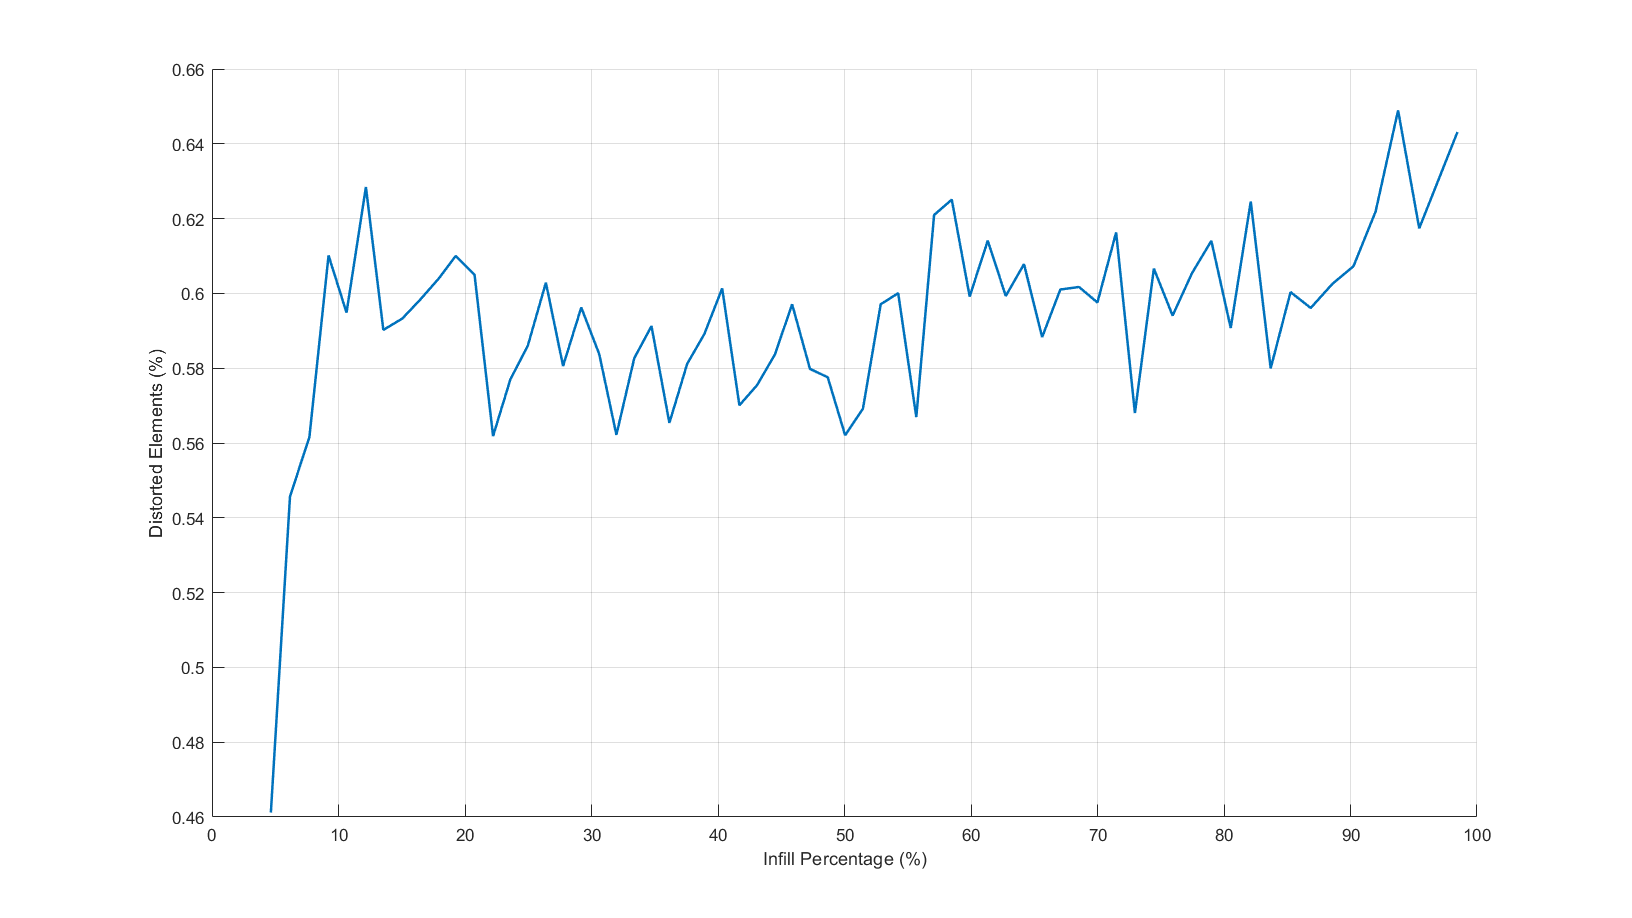

cFigure;
hold on; grid on;
plot(vertcat(summaryStruct.infill_percentage), (vertcat(summaryStruct.distortedElements)./vertcat(summaryStruct.numElements)*100),'Color',blue, 'LineWidth', 1.5)

xlabel("Infill Percentage (%)")
ylabel("Distorted Elements (%)")

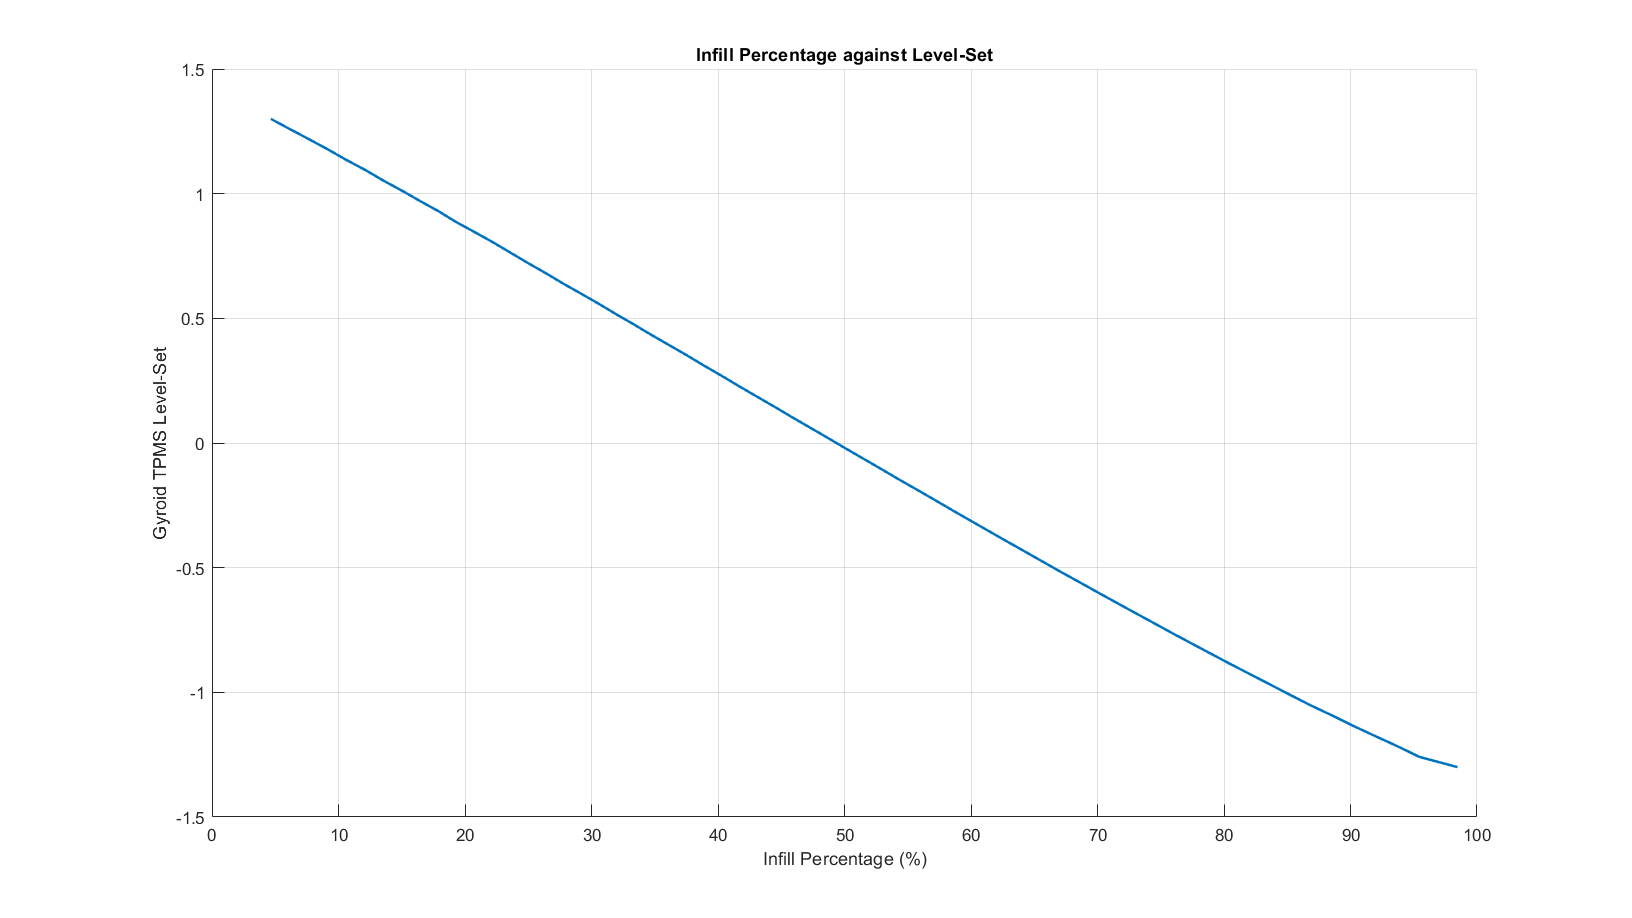

cFigure;
hold on; grid on;
plot(vertcat(summaryStruct.infill_percentage), vertcat(summaryStruct.level_set),'Color',blue, 'LineWidth', 1.5)

title("Infill Percentage against Level-Set")
xlabel("Infill Percentage (%)")
ylabel("Gyroid TPMS Level-Set")


% xlim([90 100])
% ylim([-1.32 -1.1])

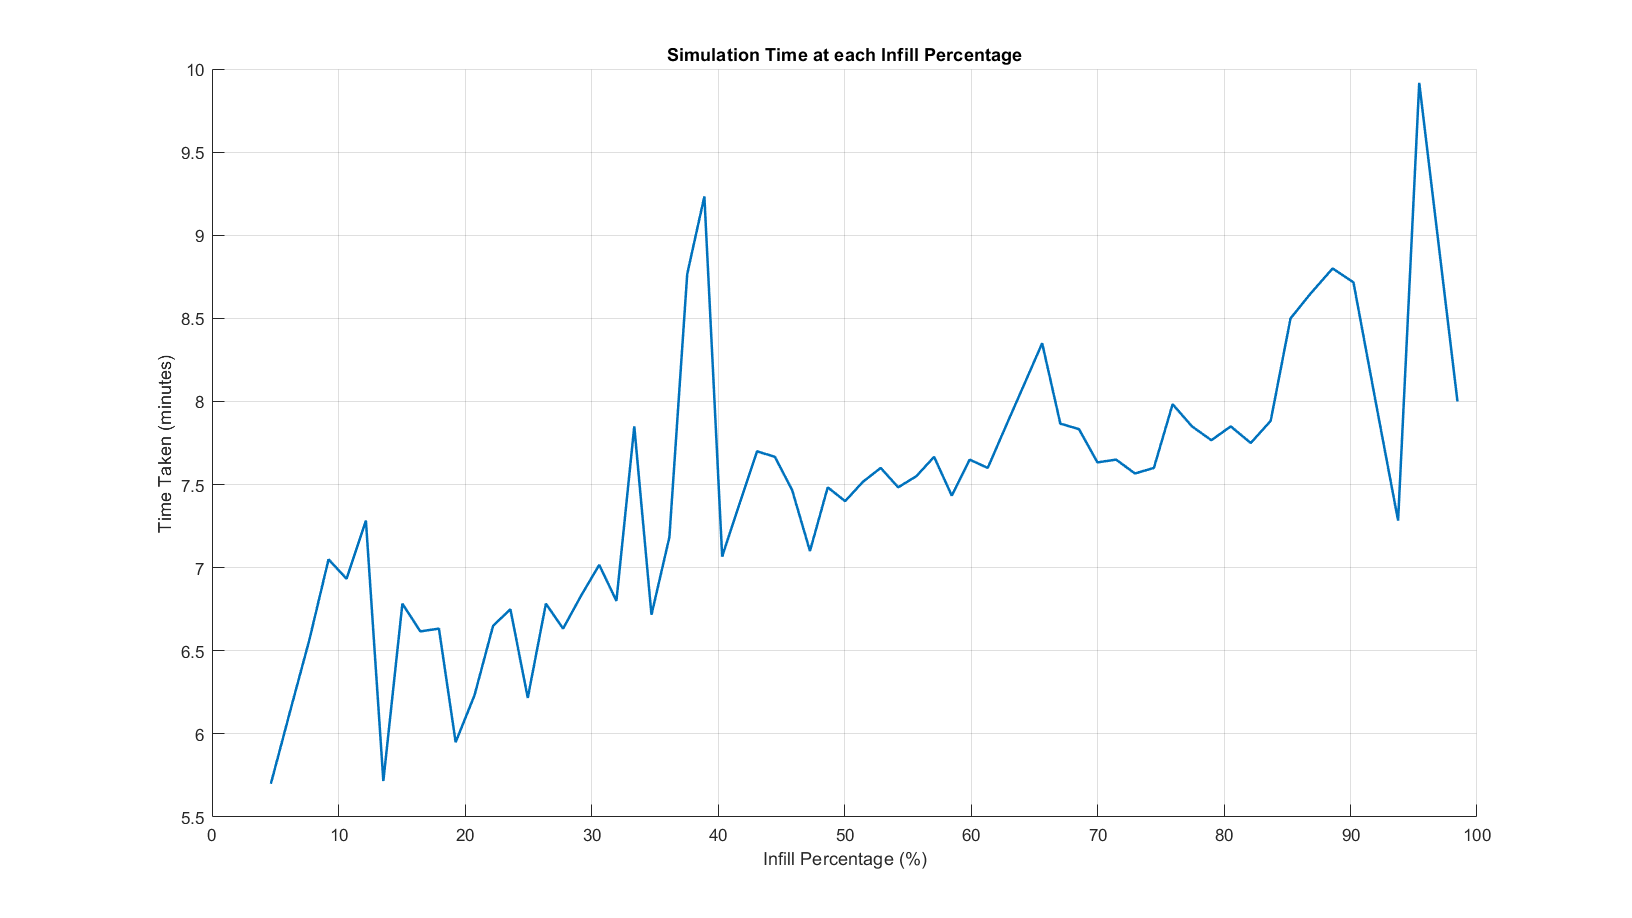

% Extract timestamp strings
timestampStrings = {summaryStruct.timestamp};
timestamps = datetime(timestampStrings, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');

timeDifferences = [NaN, minutes(diff(timestamps))]; % add NaN for the first entry
infillPercentages = vertcat(summaryStruct.infill_percentage);

cFigure;
hold on; grid on;

timeDifferences(timeDifferences > 10) = NaN; % Replace with NaN to use fillmissing
timeDifferencesFilled = fillmissing(timeDifferences, 'linear');

plot(infillPercentages, timeDifferencesFilled,'Color',blue, 'LineWidth', 1.5);

xlabel("Infill Percentage (%)");
ylabel("Time Taken (minutes)");
title("Simulation Time at each Infill Percentage");

master_csv = 'C:\Users\rusco\OneDrive - University of Warwick\Admin\Archives\Documents\GitHub\LatticeWorks\LogsActual\master.csv';

data = readtable(master_csv);

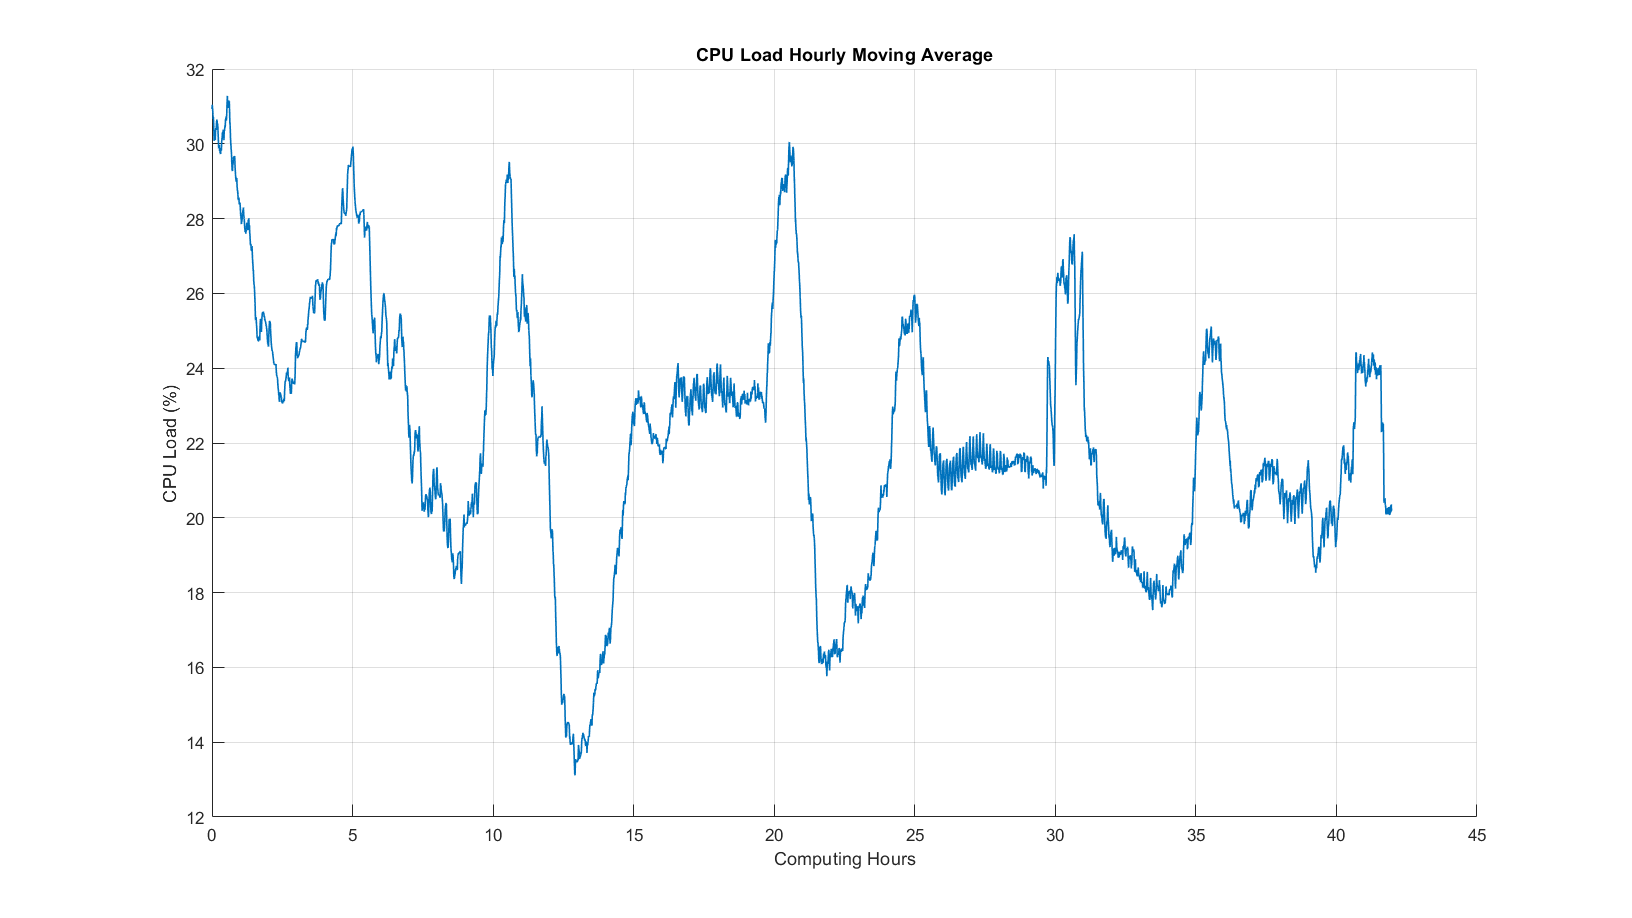

data.Time = datetime(data.Time, 'InputFormat', 'dd/MM/yyyy HH:mm:ss.SSS');

cFigure;
hold on; grid on;
% plot(data.Time, data.ProcessorTime_)

time_indices = (1:numel(data.ProcessorTime_)) * 5; % 5 comes from the logging frequency (1 every 5 seconds)
time_indices = time_indices / 60^2; % Convert to hours

% plot(time_indices, data.ProcessorTime_)

windowSize = 3600/5; % Hourly moving average (accounts for 5s sampling)
smoothed_data = movmean(data.ProcessorTime_, windowSize);
plot(time_indices, smoothed_data,'Color',blue, 'LineWidth', 1)

title("CPU Load Hourly Moving Average")
xlabel("Computing Hours")
ylabel("CPU Load (%)")

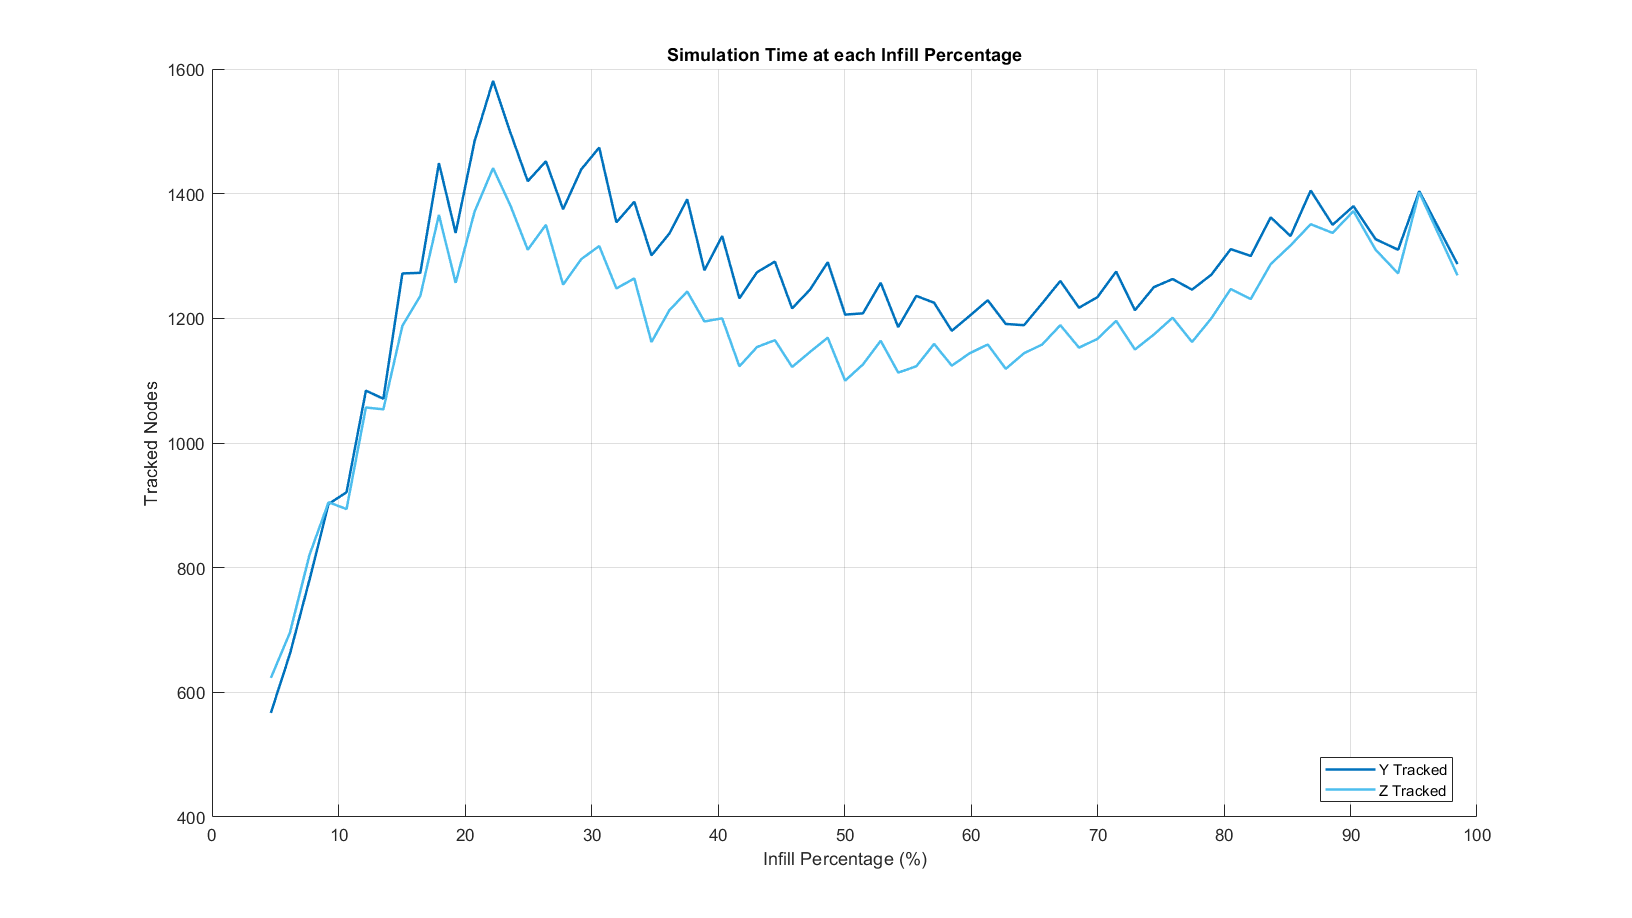

numEntries = size(summaryStruct,2);
TrackZ = zeros(1,numEntries);
TrackY = zeros(1,numEntries);

for i = 1:numEntries
    TrackZ(i) = numel(summaryStruct(i).bcSets.bcTrackZ);
    TrackY(i) = numel(summaryStruct(i).bcSets.bcTrackY);
end

cFigure;
hold on; grid on;

plot(infillPercentages, TrackY,'Color',blue, 'LineWidth', 1.5);
plot(infillPercentages, TrackZ,'Color',cyan, 'LineWidth', 1.5);


xlabel("Infill Percentage (%)");
ylabel("Tracked Nodes");
title("Simulation Time at each Infill Percentage");
legend('Y Tracked','Z Tracked','Location','best');

% savePath = fullfile(defaultFolder,'!Summary');
% mkdir(savePath);
% 
% figurePath = fullfile(savePath,'Summary Figures');
% mkdir(figurePath);
% 
% saveFigures(figurePath,true,0);